SPS_st.name='SPS'; 
SPS_st.lat=NaN;
SPS_st.lon=NaN;
SPS_st.alt=NaN;

SPS_rd=read_betsy('SPS_head',SPS_st.name);

datevec(SPS_rd.Time(1))

ans =         1993           7           2           0           0           0

datevec(SPS_rd.Time(end))

ans =         2001           7           1           0           0           0

prctile(SPS_rd.U_S,[5, 50, 95])

ans =    1.0e+03 *
    0.0521    0.0934    9.9990

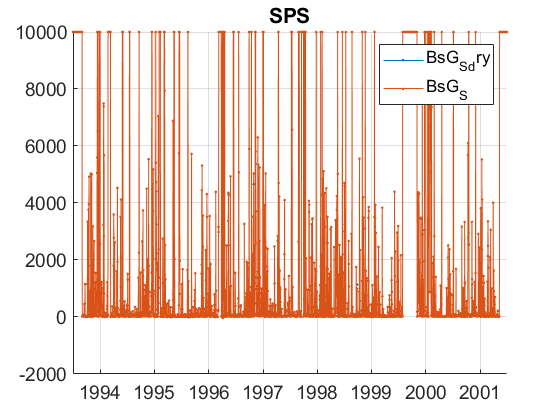

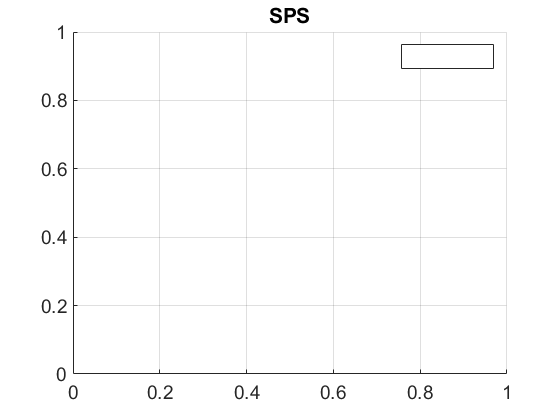

plotFigControl(SPS_rd,SPS_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives

% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE3=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% SPS_cal=compute_exp_SSA(SPS_rd,lambdaSC, lambdaAE3);
% plotFigControl_cal(SPS_cal, SPS_st.name);

%Questions:
%problems:
% hole from end 2009 to April 2016

SPS_t=timetable(SPS_rd.Time);
% begin at the beginning of a year:2002
%end year: 2009 --> 7y too short


